# Signal and noise analysis for the head direction variable

Shown as a function of position on the track, and of the number of neurons included in the ensemble.

sm = SessManager;
if ~exist('head_direction_adjacent_metrics_events.mat', 'file')
    n_reps = 80;
    d_neu = 10;

    progressbar('sess', 'size');

    [signal, noise, noise_shuf, n_sizes] = deal(cell(sm.num_usable, 1));
    for s_i = 1:sm.num_usable
        d = sm.cons_usable(s_i);
        [signal{s_i}, noise{s_i}, noise_shuf{s_i}, n_sizes{s_i}] = signal_and_noise_HD_series_cv(d, d_neu, n_reps);
        progressbar(s_i/sm.num_usable, []);
    end
    save head_direction_adjacent_metrics_events.mat signal noise noise_shuf n_sizes
else
    load head_direction_adjacent_metrics_events.mat
end

snr = cellfun(@rdivide, signal, noise, 'UniformOutput', false);
snr_shuf = cellfun(@rdivide, signal, noise_shuf, 'UniformOutput', false);

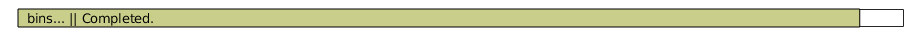

c_mean = @(y) cellfun(@(x)squeeze(mean(x,1)), y, 'UniformOutput', false);
c_conf = @(y) cellfun(@(x)1.96*squeeze(std(x,[],1)./sqrt(size(x,1))), y, 'UniformOutput', false);

s_m = c_mean(signal);
s_s = c_conf(signal);

n_m = c_mean(noise);
n_s = c_conf(noise);

ns_m = c_mean(noise_shuf);
ns_s = c_conf(noise_shuf);

snr_m = c_mean(snr);
snr_s = c_conf(snr);

snrs_m = c_mean(snr_shuf);
snrs_s = c_conf(snr_shuf);

cutoff_n = 100;
n_sizes = n_sizes(:);
[signal_slope, signal_slope_conf] = cellfun(@(n,m)Utils.fitaline(n,mean(m,2).',cutoff_n), n_sizes, s_m);
[noise_slope, noise_slope_conf] = cellfun(@(n,m)Utils.fitaline(n,mean(m,2).',cutoff_n), n_sizes, n_m);
[noise_shuf_slope, noise_shuf_slope_conf] = cellfun(@(n,m)Utils.fitaline(n,mean(m,2).',cutoff_n), n_sizes, ns_m);
noise_shuf_final = cellfun(@(~,m) mean(m(end,:),2), n_sizes, ns_m);
[asymp_snr, asymp_snr_conf] = uncertain_divide(signal_slope, signal_slope_conf, noise_slope, noise_slope_conf);
[asymp_snr_shuf, asymp_snr_shuf_conf] = uncertain_divide(signal_slope, signal_slope_conf, noise_shuf_slope, noise_shuf_slope_conf);

progressbar('bins...')
n_bins = 20;

[signal_slope_bin, signal_slope_conf_bin,...
    noise_slope_bin, noise_slope_conf_bin,...
    noise_shuf_slope_bin, noise_shuf_slope_conf_bin,...
    asymp_snr_bin, asymp_snr_conf_bin,...
    asymp_snr_shuf_bin, asymp_snr_shuf_conf_bin] = deal(zeros(sm.num_usable, n_bins));

for b = 1:n_bins
    [signal_slope_bin(:,b), signal_slope_conf_bin(:,b)] = cellfun(@(n,m)Utils.fitaline(n,m(:,b).',cutoff_n), n_sizes, s_m);
    [noise_slope_bin(:,b), noise_slope_conf_bin(:,b)] = cellfun(@(n,m)Utils.fitaline(n,m(:,b).',cutoff_n), n_sizes, n_m);
    [noise_shuf_slope_bin(:,b), noise_shuf_slope_conf_bin(:,b)] = cellfun(@(n,m)Utils.fitaline(n,m(:,b).',cutoff_n), n_sizes, ns_m);
    [asymp_snr_bin(:,b), asymp_snr_conf_bin(:,b)] = uncertain_divide(signal_slope_bin(:,b), signal_slope_conf_bin(:,b), noise_slope_bin(:,b), noise_slope_conf_bin(:,b));
    [asymp_snr_shuf_bin(:,b), asymp_snr_shuf_conf_bin(:,b)] = uncertain_divide(signal_slope_bin(:,b), signal_slope_conf_bin(:,b), noise_shuf_slope_bin(:,b), noise_shuf_slope_conf_bin(:,b));
    progressbar(b/n_bins);
end


[~, mice] = SessManager.usable_sess_id_list;

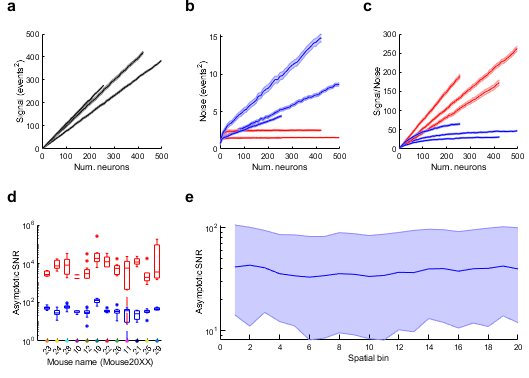

ix_special = SessManager.special_sessions_usable_index({'Mouse2022', 'Mouse2024', 'Mouse2028'});

p = Pub(14, 10, 'rows', 2, 'columns', 3);

p.panel(1, 'xlab', 'Num. neurons', 'ylab', 'Signal (events^2)');
for ix = ix_special
    serrorbar(n_sizes{ix}, mean(s_m{ix},2), sqrt(mean(s_s{ix}.^2,2)), 'k');
end

p.panel(2, 'xlab', 'Num. neurons', 'ylab', 'Noise (events^2)');
for ix = ix_special
    serrorbar(n_sizes{ix}, mean(ns_m{ix},2), sqrt(mean(ns_s{ix}.^2,2)), 'r');
    serrorbar(n_sizes{ix}, mean(n_m{ix},2), sqrt(mean(n_s{ix}.^2,2)), 'b');
end

p.panel(3, 'xlab', 'Num. neurons', 'ylab', 'Signal/Noise');
for ix = ix_special
    serrorbar(n_sizes{ix}, mean(snrs_m{ix},2), mean(snrs_s{ix},2), 'r');
    serrorbar(n_sizes{ix}, mean(snr_m{ix},2), mean(snr_s{ix},2), 'b');
end
%panel 4: asymp snr boxplot
p.panel(4, 'xlab', 'Mouse name (Mouse20XX)', 'ylab', 'Asymptotic SNR');
hold on;
bf_ = @(x, c) boxplot(x, Utils.cf_(@(x)x(end-1:end), mice), 'Colors', c, 'BoxStyle', 'outline', 'Symbol', '.');
bf_(asymp_snr, 'b');
bf_(asymp_snr_shuf, 'r');
xtickangle(45);
set(gca, 'YScale', 'log');
x_coords = get(gca, 'XTick');
mouse_id = get(gca, 'XTickLabel');
mouse_id = Utils.cf_(@(x)['Mouse20' x], mouse_id);
mouse_colors = DecodeTensor.mcolor(mouse_id);
ylim([1 1e6]);
for i = 1:numel(x_coords)
    x_val = x_coords(i);
    color = mouse_colors{i};
    hold on;
    y_bottom = ylim;
    y_bottom = y_bottom(1);
    scatter(x_val, y_bottom, 8, color, 'filled');
end
%panel 5 & 6: line plots showing asymp snr per bin category, real and
%shuffled
p.panel([5 6], 'xlab', 'Spatial bin', 'ylab', 'Asymptotic SNR');
a = asymp_snr_bin;
%a_(a_<0) = nan;
%hs = plot(1:20, a_, 'Color', [0.8 0.8 1]);
%hold on;
%hm = plot(1:20, median(asymp_snr_bin), 'Color', 'b');
shadedErrorBar(1:20, median(a), [quantile(a,0.75) ; quantile(a,0.25)], 'lineprops', 'b');
set(gca, 'YScale', 'log');

p.format;
Utils.printto('events_figs/f3_supplements', 'head_direction_signal_and_noise.pdf');

dp = real(sqrt(a));

array2table(median(dp(:,[1 10 20])), 'VariableNames', {'Bin1 d''', 'Bin10 d''', 'Bin20 d'''})

ans = 1×3 table
    Bin1 d'    Bin10 d'    Bin20 d'
    _______    ________    ________

    6.4604      5.8131      6.3201 


p_1_vs_10 = signrank(dp(:,1), dp(:,10))

p_1_vs_10 = 0.0341

p_20_vs_10 = signrank(dp(:,20), dp(:,10))

p_20_vs_10 = 0.3947

p_1_vs_20 = signrank(dp(:,20), dp(:,1))

p_1_vs_20 = 0.6322

dist_from_center = abs((1:20) - 10.5).';
med_asnr = median(a).';

tab = array2table([dist_from_center, sqrt(med_asnr)], 'VariableNames', {'Distance', 'dprime'});
%fitlm(dist_from_center, sqrt(med_asnr))
fitlm(tab, 'dprime ~ 1 + Distance')

ans = Linear regression model:
    dprime ~ 1 + Distance

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)       5.833     0.08157    71.509    1.4933e-23
    Distance       0.064345    0.014146    4.5486    0.00024887


Number of observations: 20, Error degrees of freedom: 18
Root Mean Squared Error: 0.182
R-squared: 0.535,  Adjusted R-Squared: 0.509
F-statistic vs. constant model: 20.7, p-value = 0.000249

[p,pp,s,sp,k,kp,adjr2] = Org.corr_check(dist_from_center, med_asnr);
fprintf('Sessionwise correlations %s vs. %s: adj. R^2 = %.3f\n', 'squared distance from center', 'median asymptotic SNR of head direction', adjr2);

Sessionwise correlations squared distance from center vs. median asymptotic SNR of head direction: adj. R^2 = 0.514


fprintf('Pearson: %.3f, p = %e, %s\n', p, pp, Utils.pstar(pp));

Pearson: 0.734, p = 2.277820e-04, ***


fprintf('Spearman: %.3f, p = %e, %s\n', s, sp, Utils.pstar(sp));

Spearman: 0.691, p = 7.358893e-04, ***


fprintf('Kendall: %.3f, p = %e, %s\n', k, kp, Utils.pstar(kp));

Kendall: 0.530, p = 1.557285e-03, **


## Saving the results for later analysis

Name the variables with names specific to head direction, to avoid conflicts later:

hd_asymp_snr = asymp_snr;
hd_asymp_snr_conf = asymp_snr_conf;
hd_asymp_snr_shuf = asymp_snr_shuf;
hd_asymp_snr_shuf_conf = asymp_snr_shuf_conf;

save hd_signal_noise_save.mat hd_asymp_snr hd_asymp_snr_conf hd_asymp_snr_shuf hd_asymp_snr_shuf_conf

figure; org.correlogram('hd_efn', 'hd_inv_asymp_ratio', true, true, true);

Using only 34 out of 110 sessions
Mouse-aggregated correlations hd_efn vs. hd_inv_asymp_ratio: adj. R^2 = 0.818
Pearson: 0.919, p = 1.263007e-03, **
Spearman: 0.833, p = 1.537698e-02, *
Kendall: 0.714, p = 1.413690e-02, *


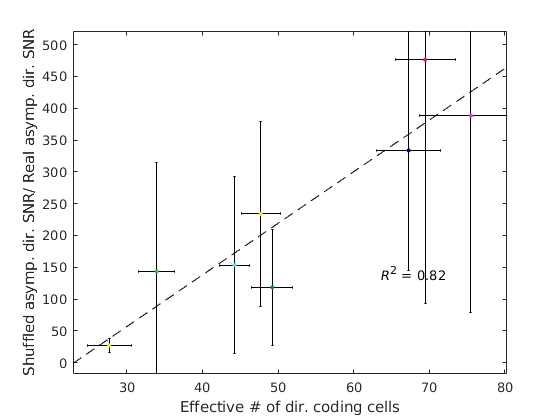

xlabel 'Effective # of dir. coding cells'
ylabel 'Shuffled asymp. dir. SNR/ Real asymp. dir. SNR'
Utils.printto('events_figs/f4_supplements', 'HD_asymp_ratio_efn.pdf');

Using only 34 out of 110 sessions
Mouse-aggregated correlations num_neurons vs. hd_inv_asymp_ratio: adj. R^2 = 0.648
Pearson: 0.836, p = 9.799312e-03, **
Spearman: 0.762, p = 3.675595e-02, *
Kendall: 0.571, p = 6.101190e-02, n.s


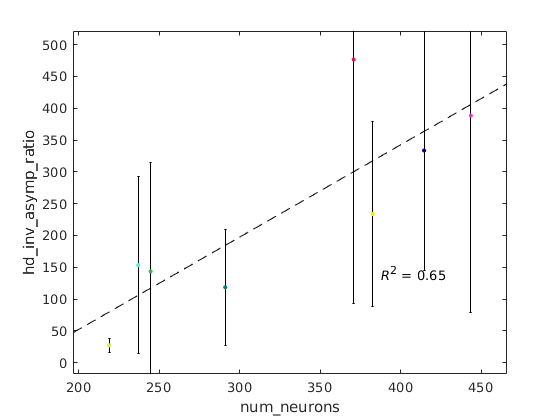

figure; org.correlogram('num_neurons', 'hd_inv_asymp_ratio', true, true, true);

f_ = org.sess_prop.hd_inv_asymp_ratio > org.sess_prop_conf.hd_inv_asymp_ratio;
fitlm([zscore(org.sess_prop.num_neurons(f_)), zscore(org.sess_prop.hd_efn(f_))], zscore(org.sess_prop.hd_inv_asymp_ratio(f_)))

ans = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                    Estimate         SE          tStat        pValue  
                   ___________    ________    ___________    _________

    (Intercept)    -1.1353e-16    0.090566    -1.2535e-15            1
    x1               -0.032371     0.17161       -0.18863      0.85134
    x2                 0.84211     0.17161         4.9071    1.591e-05


Number of observations: 43, Error degrees of freedom: 40
Root Mean Squared Error: 0.594
R-squared: 0.664,  Adjusted R-Squared: 0.647
F-statistic vs. constant model: 39.5, p-value = 3.34e-10

# Functions

Measuring the signal and noise as a function of the positional bins, of the direction of motion (head direction) signal. The variances of the left and right clouds are averaged (measured along the head direction signal direction). This function takes a particular ensemble size and subsamples the full data tensor accordingly.

function [dmu2, s2, s2s] = sn_HS_cv(o, n_size)
[data_tensor, tr_dir] = DecodeTensor.cut_tensor(o.data_tensor, o.tr_dir, n_size, []);
[T1, d1, T2, d2, ~] = DecodeTensor.holdout_half(data_tensor, tr_dir);
%T1s = DecodeTensor.shuffle_tensor(T1, d1);
T2s = DecodeTensor.shuffle_tensor(T2, d2);
[~, K, ~] = size(T1);

%n_ize = @(x) x./(norm(x)+eps);
%ndir = @(x, S) dot(x, S*x(:));

[dmu2, s2, s2s] = deal(zeros(K, 1));
sq = @(x) permute(x, [3 1 2]);
for k = 1:K
    X1_R = sq(T1(:,k,d1== 1));
    X1_L = sq(T1(:,k,d1==-1));
    
    %X1_Rs = squeeze(T1s(:,k,d1== 1)).';
    %X1_Ls = squeeze(T1s(:,k,d1==-1)).';
    
    
    X2_R = sq(T2(:,k,d2== 1)); m2_R = mean(X2_R, 1);
    X2_L = sq(T2(:,k,d2==-1)); m2_L = mean(X2_L, 1);
    
    X2_Rs = sq(T2s(:,k,d2== 1)); m2_Rs = mean(X2_Rs, 1);
    X2_Ls = sq(T2s(:,k,d2==-1)); m2_Ls = mean(X2_Ls, 1);
    
    
    model_dmu = mean(X1_R,1) - mean(X1_L,1);
    dmu_normed = (model_dmu./(eps+norm(model_dmu))).';
    
    my_dmu = m2_R - m2_L;
    if ~isequal(size(dmu_normed.'), size(my_dmu))
        keyboard;
    end
    dmu2(k) = (my_dmu * dmu_normed).^2;
    
    %my_sigma = (cov(X2_R) + cov(X2_L))/2;
    %s2(k) = ndir(dmu_normed, my_sigma);
    %my_sigma_s = (cov(X2_Rs) + cov(X2_Ls))/2;
    %s2s(k) = ndir(dmu_normed, my_sigma_s);
    s2(k) = (var((X2_R - m2_R)*dmu_normed) + var((X2_L - m2_L)*dmu_normed))/2;
    s2s(k) = (var((X2_Rs - m2_Rs)*dmu_normed) + var((X2_Ls - m2_Ls)*dmu_normed))/2;
end
end

function [dm2, sm, sms, n_sizes] = signal_and_noise_HD_series_cv(o, d_neu, n_reps, only_nsizes)
if ~exist('only_nsizes', 'var')
    only_nsizes = false;
end
[n_max, K, ~] = size(o.data_tensor);
n_sizes = unique([1, d_neu:d_neu:n_max, n_max]);
[dm2, sm, sms] = deal(zeros(n_reps, numel(n_sizes), K));

if only_nsizes
    return;
end

for n_i = 1:numel(n_sizes)
    for i = 1:n_reps
        [dm2(i, n_i, :), sm(i, n_i, :), sms(i, n_i, :)] = sn_HS_cv(o, n_sizes(n_i));
    end
    progressbar([], n_i/numel(n_sizes));
end
end

%{
function [delta_mu2, sigma2_in_delta_mu, sigma2_in_delta_mu_shuf] = signal_and_noise_HD(o, n_size)
[N, K, ~] = size(o.data_tensor);

sub_tensor = o.data_tensor(randperm(N)<=n_size,:,:);
sub_tensor_shuf = DecodeTensor.shuffle_tensor(sub_tensor, o.tr_dir);

data_R = sub_tensor(:,:,o.tr_dir==1);
data_L = sub_tensor(:,:,o.tr_dir==-1);

data_R_shuf = sub_tensor_shuf(:,:,o.tr_dir==1);
data_L_shuf = sub_tensor_shuf(:,:,o.tr_dir==-1);

mu_R = mean(data_R, 3);
mu_L = mean(data_L, 3);

res_R = data_R - mu_R;
res_L = data_L - mu_L;

res_R_shuf = data_R_shuf - mu_R;
res_L_shuf = data_L_shuf - mu_L;

delta_mu = mu_R - mu_L;

[delta_mu2, proj_var_R, proj_var_R_shuf,...
    proj_var_L, proj_var_L_shuf] = deal(zeros(K, 1));

for b = 1:K
    delta_mu2(b) = norm(delta_mu(:,b)).^2;
    
    proj_var_R(b) = var((delta_mu(:,b).'./sqrt(delta_mu2(b))) * squeeze(res_R(:, b, :)));
    proj_var_L(b) = var((delta_mu(:,b).'./sqrt(delta_mu2(b))) * squeeze(res_L(:, b, :)));
    
    proj_var_R_shuf(b) = var((delta_mu(:,b).'./sqrt(delta_mu2(b))) * squeeze(res_R_shuf(:, b, :)));
    proj_var_L_shuf(b) = var((delta_mu(:,b).'./sqrt(delta_mu2(b))) * squeeze(res_L_shuf(:, b, :)));
end

sigma2_in_delta_mu = (proj_var_R + proj_var_L)/2;
sigma2_in_delta_mu_shuf = (proj_var_R_shuf + proj_var_L_shuf)/2;
end

function [dm2, sm, sms, n_sizes] = signal_and_noise_HD_series(o, d_neu, n_reps)
[n_max, K, ~] = size(o.data_tensor);
n_sizes = unique([1, d_neu:d_neu:n_max, n_max]);
[dm2, sm, sms] = deal(zeros(n_reps, numel(n_sizes), K));

for n_i = 1:numel(n_sizes)
    for i = 1:n_reps
        [dm2(i, n_i, :), sm(i, n_i, :), sms(i, n_i, :)] = signal_and_noise_HD(o, n_sizes(n_i));
        progressbar([], [], i/n_reps);
    end
    progressbar([], n_i/numel(n_sizes), []);
end
end
%}